# Problem #4

This program aims to calculate the optimal initial mass for the first stage of a two-stage rocket. A plot of initial mass of 1st stage vs velocity ratio 1 will be manipulated.

**>> Given Data**

- required total velocity $\Delta V=12\;\frac{\mathrm{km}}{s}=12000\;\frac{m}{s}$

- payload mass $m_{\mathrm{pay}} =80\;\mathrm{kg}$

- inert mass ratio $f_{\mathrm{inert}\;} =\frac{1}{12}\approx \;0\ldotp 0833\;$

- specific impulse for 1st stage $I_{\mathrm{sp1}} \;=280\;s$

- specific impulse for 2nd stage $\;I_{\mathrm{sp2}} \;=350\;s$

**>> Assumptions**

- ideal conditions 

- no gravity loss

- perfectly expanded nozzle 

**>> Equations Used **

- 
$$\Delta V\;=\Delta V_1 +\Delta V_2 \;\;\;\;\;\;\;\cdots \left(1\right)$$


-  
$$\Delta V_1 =f_1 \cdot \Delta V,\;\;\;\;\;\;\Delta V_{2\;} \;=f_2 \cdot \Delta V$$


- 
$$f_1 +f_2 \;=1\;\;\;\;\;\;\cdots \left(2\right)$$


- 
$$m_{\mathrm{initial},\mathrm{stage1}\;} =m_{\mathrm{pay}} \cdot {\left(1-f_{\mathrm{inert}} \right)}^n \cdot \prod \left\lbrack \frac{e^{\frac{\Delta V_n }{C_n }} }{1-f_{\mathrm{inert}} \cdot e^{\frac{\Delta V_n }{C_n }} }\;\;\right\rbrack \cdots \left(3\right)$$
     
$$\begin{array}{l}
\mathrm{mass}\;\mathrm{of}\;\mathrm{propellent}=m_{\mathrm{prop}\;} =m_{\mathrm{pay}} \cdot {\left(1-f_{\mathrm{inert}} \right)}^n \cdot \prod \left\lbrack \frac{\left(e^{\frac{\Delta V_n }{C_n }} -1\right)}{1-f_{\mathrm{inert}} \cdot e^{\frac{\Delta V_n }{C_n }} }\right\rbrack \;\;\cdots \left(4\right)\;\\
\mathrm{where}\;\;\;\;\;\;\;\;\;\;\;c=\mathrm{effective}\;\;\mathrm{exhaust}\;\;\;\mathrm{velocity},\mathrm{and}\;\;n=#\;\mathrm{of}\;\mathrm{stages}\\
\mathrm{or}\;{\;\;\;\;\;\;\;\;\;m}_{\mathrm{prop}} \;=\left(1-f_{\mathrm{inert}} \right)\left(m_{\mathrm{initial}} -m_{\mathrm{pay}} \right)\;\;\;\;\;\;\;\cdots \left(5\right)
\end{array}$$


from equations (1) - (3) we obtain for a two-stage rocket


$$m_{\mathrm{initial},\mathrm{stage1}} \left(f_1 \right)\;=\frac{m_{\mathrm{pay}} \cdot e^{\left(\frac{f_1 \Delta V}{C_1 }\;+\frac{\left(1-f_1 \right)\Delta V}{C_2 }\right)} {\left(1-f_{\mathrm{inert}} \right)}^2 }{\left(1-f_{\mathrm{inert}} \cdot e^{\frac{f_1 \Delta V}{C_1 }} \right)\left(1-f_{\mathrm{inert}} \cdot e^{\frac{\left(1-f_1 \right)\Delta V}{C_2 }} \right)}$$



$$m_{\mathrm{prop},\mathrm{stage1}} \left(f_1 \right)\;=\frac{m_{\textrm{pay}} \cdot \left({1-e}^{\frac{f_1 \Delta V}{C_1 }} \right)\left(1-e^{\frac{\left(1-f_1 \right)\Delta V}{C_2 }} \;\right){\left(1-f_{\textrm{inert}} \right)}^2 }{\left(1-f_{\textrm{inert}} \cdot e^{\frac{f_1 \Delta V}{C_1 }} \right)\left(1-f_{\textrm{inert}} \cdot e^{\frac{\left(1-f_1 \right)\Delta V}{C_2 }} \right)}$$


and $\;\;c=g_0 \cdot I_{\mathrm{sp}}$ where $g_0 =\mathrm{gravitational}\;\mathrm{accleration}=9\ldotp 81\;\frac{m}{s^2 }$

## Algorithm

% Assigning variables to given values 
% Required total velocity [m/s]
V_tot = 12000;
% Payload mass [kg]
m_pay = 80;
% Inert mass ratio 
f_inert = 0.0833;
% Specific impulse for stage 1 [s]
Isp1 = 280;
% Spedific impulse for stage 2 [s]
Isp2 = 350;
% Gravitational acceleration [m/s^2]
g_o = 9.81;

% Since f1 has an optimum value interval of [0.3, 0.55] create the array for f1 values as
f1 = 0.3:0.001:0.55;
% Break down the equation to calculate the initial mass of stage 1 
% Component 1 
comp1 = exp(f1 * V_tot / g_o / Isp1);
% Component 2 
comp2 = exp((1 - f1) * V_tot / g_o / Isp2);
% Thus, the initial mass of stage 1 becomes
m_stage1 = m_pay .* comp1 .* comp2 * (1 - f_inert)^2 ./ (1 - f_inert.*comp1)...
    ./ (1 - f_inert.*comp2);

% Finding the minimum mass for stage 1
m_min = min(m_stage1);
% The index of this minimum value 
idx = find(m_stage1 == m_min);
% The corresponding f1 value
f1_min = f1(idx);
% Find f2 corresponding to this f1 value 
f2_min = 1 - f1_min;
% Find the corresponding mass of propellent using equation (4)
% First manipulate the components to match the f1 with f1_min
comp1_min = exp(f1_min * V_tot / g_o / Isp1);  % Component 1
comp2_min = exp((1 - f1_min) * V_tot / g_o / Isp2); % Component 2
% Mass of propllent is 
m_prop_min =  m_pay * (1 - comp1_min) * (1 - comp2_min) * (1 - f_inert)^2 ...
    / (1 - f_inert*comp1_min) / (1 - f_inert*comp2_min);

## Plotting

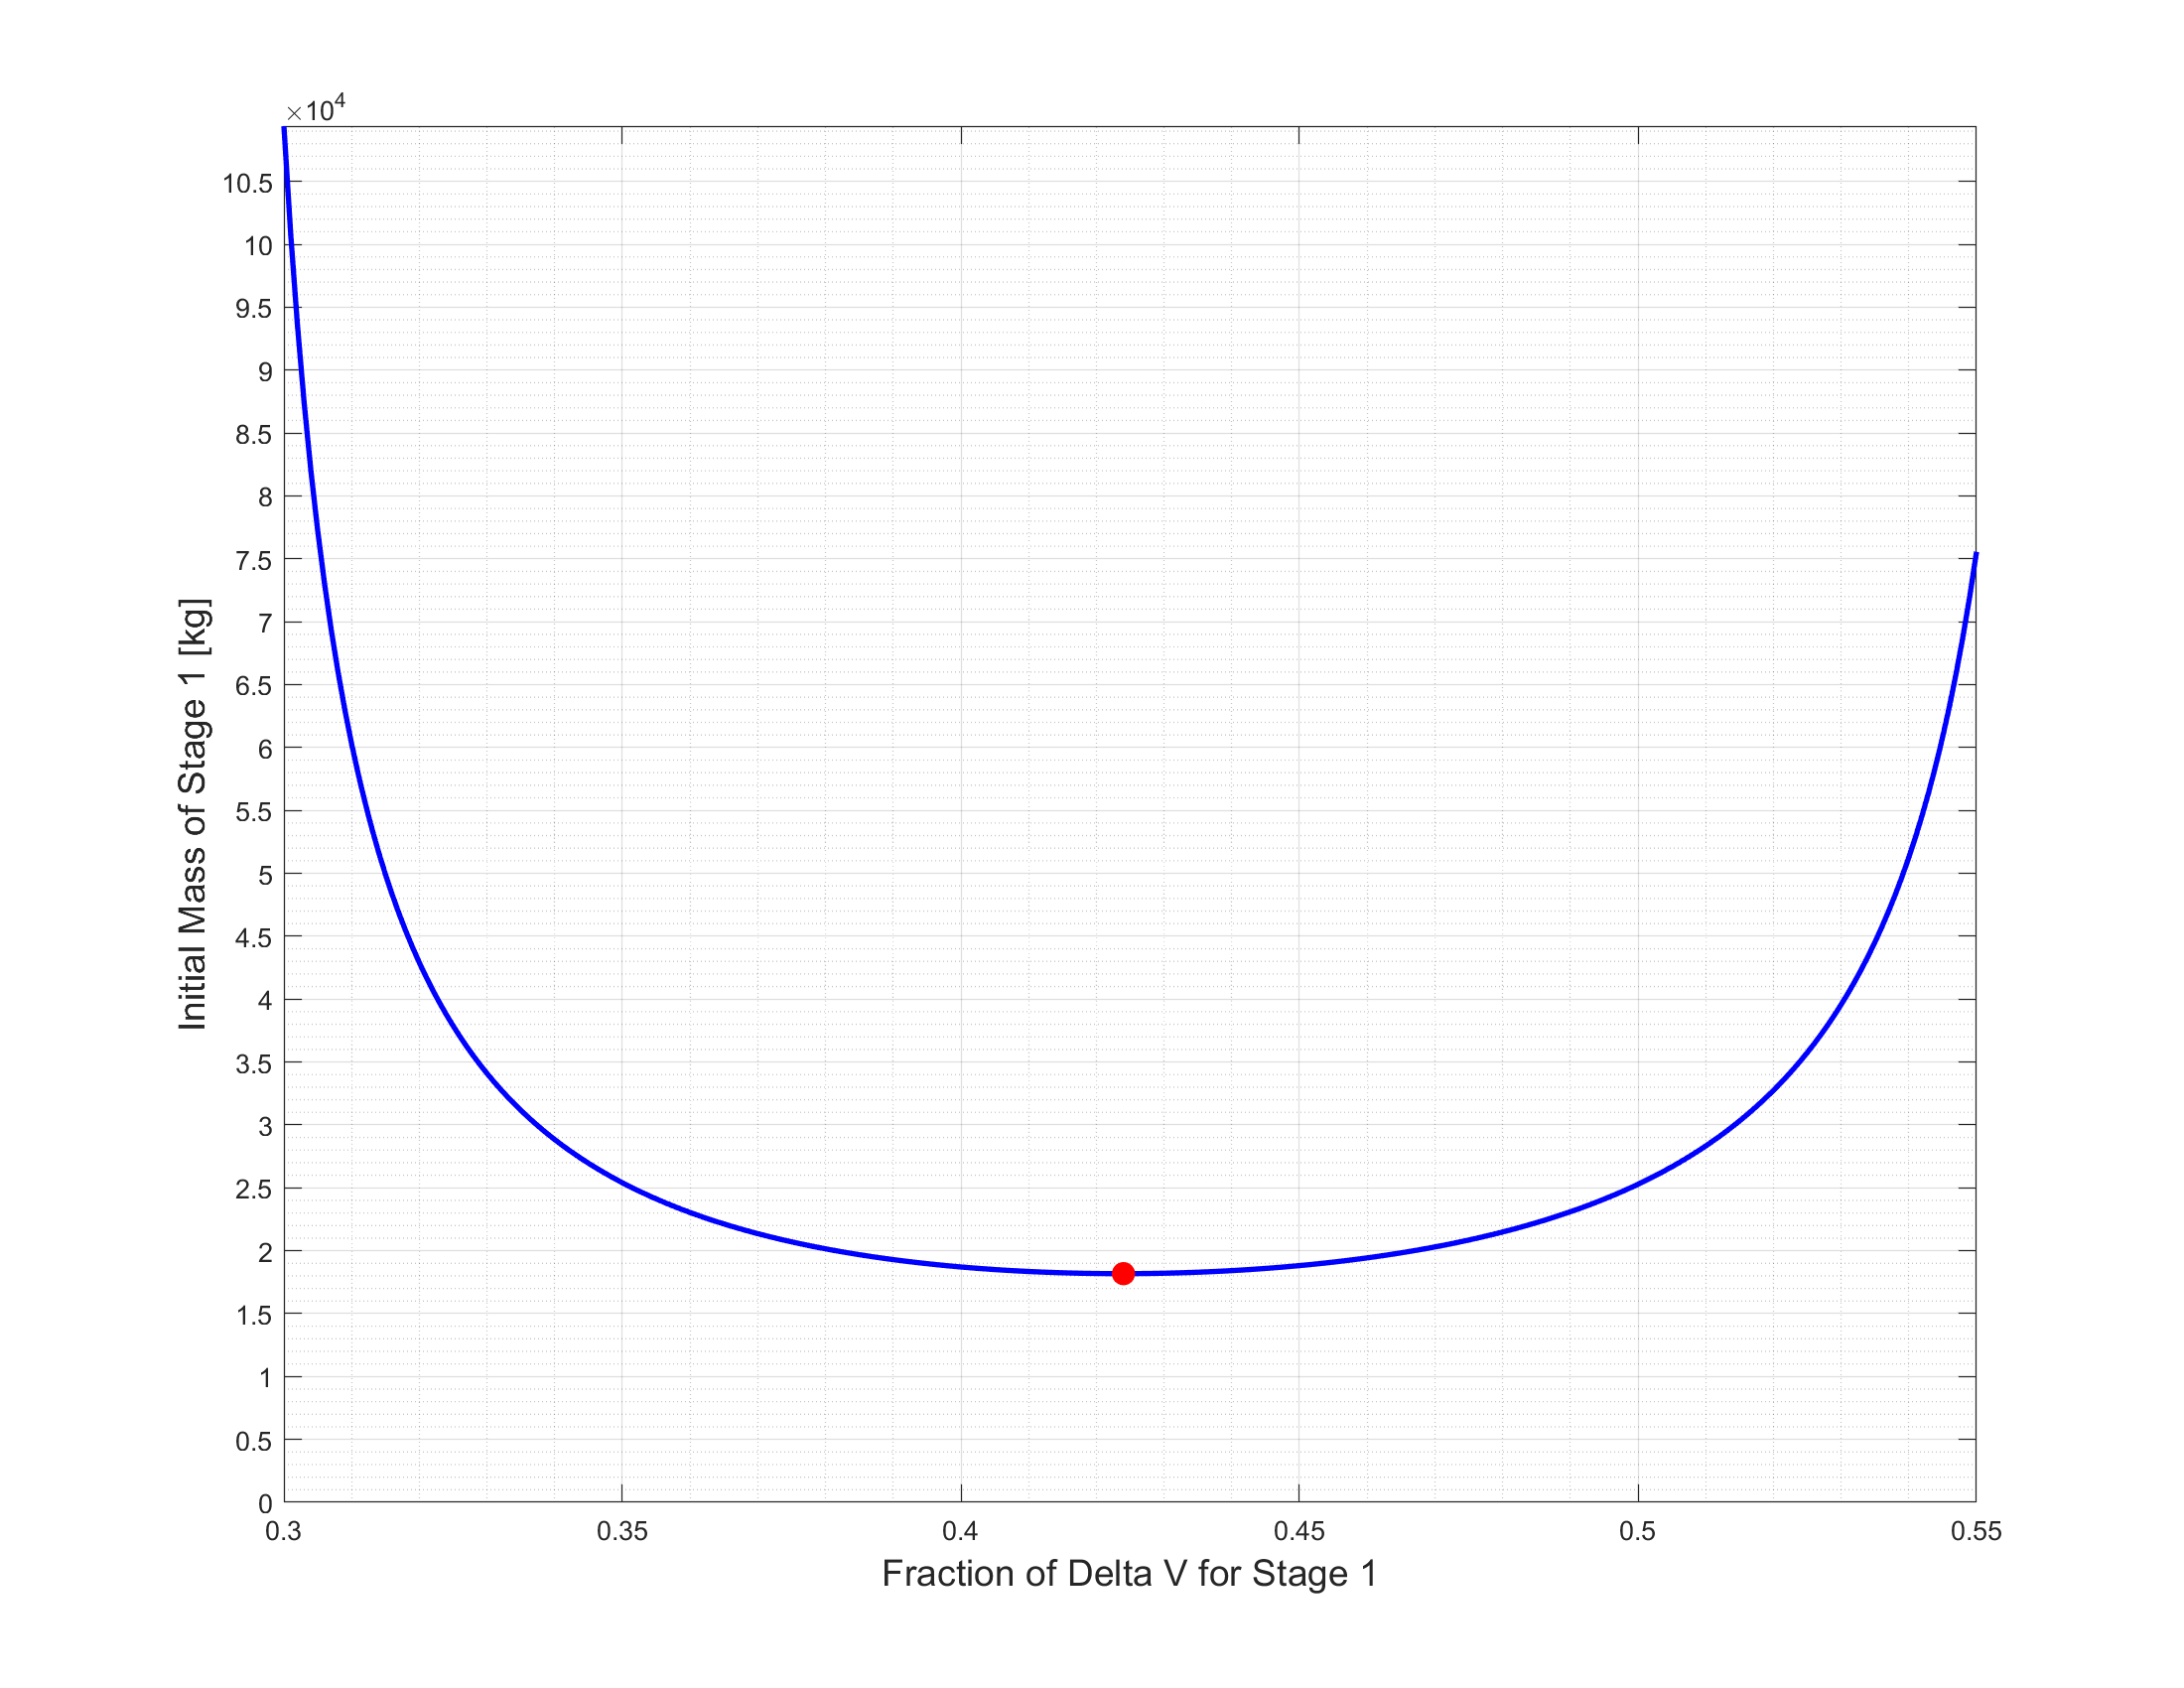

% Adjusting fontsize and linewidth
fontsize = 14;
linewidth = 2;

% Plotting commands
figure(1)
plot(f1, m_stage1,'-b','Linewidth',linewidth)
axis([0.3 0.55 0 inf])
yticks(0:5000:110000)
xlabel('Fraction of Delta V for Stage 1', 'FontSize',fontsize)
ylabel('Initial Mass of Stage 1 [kg]', 'FontSize',fontsize)
grid on
grid minor
box on
hold on
plot(f1_min, m_min, '.r', 'MarkerSize',30)
% Control where plot is positioned
set(gcf,'PaperPositionMode','auto','Position',[0 0 1100 850])

## Results

fprintf(fid,['The initial mass of stage 1 is at minimum when f1 = %.3f',...

The initial mass of stage 1 is at minimum when f1 = 0.424 with a value of 18176.37 kg.

    'with a value of %.2f kg.'], f1_min, m_min);
fprintf(fid,['At this minimum value f2 = %.3f',... 

At this minimum value f2 = 0.576 and the mass of the propellent is 13278.03 kg.

    'and the mass of the propellent is %.2f kg.'], f2_min, m_prop_min);